%% Alongtrack from OceanDB (array structure)
%eddyPath_track from eddy tracking algorithm
% no eddy field
clear all

## 1. Load extracted tracks along the eddy path

eddy_id='+527413';
filename = strcat(['G:/My Drive/AlongTrack/MyCode/eddy_',eddy_id,'.nc']);
timeo = ncread(filename,'eddy/time')+datenum(1950,01,01); %Initial time is also a free parameter
eddy_time = timeo-min(timeo);
eddyPath.lat = ncread(filename,'eddy/latitude');
eddyPath.lon = ncread(filename,'eddy/longitude');

%if you want to change the eddyPath to a function handle
eddyPath_fun_t.lon = @(t) interp1(eddy_time, eddyPath.lon, t, 'linear', 'extrap');
eddyPath_fun_t.lat = @(t) interp1(eddy_time, eddyPath.lat, t, 'linear', 'extrap');
% Function to convert any lat/lon to x/y relative to the eddy center at time t
get_eddyPath_xy = @(lat, lon, t) latlon2xy(lat, lon, eddyPath_fun_t.lat(t),eddyPath_fun_t.lon(t));


%already extracted alongtrack
at_time = ncread(filename,'alongtrack/time')+datenum(1950,01,01);
at_lat = ncread(filename,'alongtrack/latitude');
at_lon = ncread(filename,'alongtrack/longitude');
at_sla = ncread(filename,'alongtrack/sla_filtered');
at_tracknumber = ncread(filename,'alongtrack/track');

%array of all tracks (no need to repeat)
alongtrackLatLon.t=at_time;
alongtrackLatLon.lat=at_lat;
alongtrackLatLon.lon=at_lon;
alongtrackLatLon.ssh=at_sla;


% other option to get it from Jonathan's nc 3D file.
my_readdir = 'G:\My Drive\AlongTrack\';
%% Alongtrack from Jonathan (3D matrix [atd, tracknumber, cycle])
JasonAlongTrack.filename = strcat(readdir, 'JasonAlongTrack.nc');
JasonAlongTrack.lat = ncread(JasonAlongTrack.filename, 'lat');
JasonAlongTrack.lon = ncread(JasonAlongTrack.filename, 'lon');
%JML convert time to Matlab's datenum format
JasonAlongTrack.time = ncread(JasonAlongTrack.filename, 'time') + datenum(1950, 1, 1);
%Time is defined as beginning at 4:05 AM on Sept 23, 1992,
JasonAlongTrack.ssh = ncread(JasonAlongTrack.filename, 'sla');


% current_file_path = matlab.desktop.editor.getActiveFilename;
% [current_dir, ~, ~] = fileparts(current_file_path);
% load(strcat(current_dir,'\alongtrackLatLon_real.mat'))
alongtrackLatLon = extractAlongtrackLatLonEddyCenter(JasonAlongTrack,eddyPath,timeo,radius=300); %radius in km

## Alongtrack in x,y projection about the eddy center

[x_km, y_km]=get_eddyPath_xy(alongtrackLatLon.lat,alongtrackLatLon.lon,alongtrackLatLon.t-min(alongtrackLatLon.t));
alongtrackXY.x=x_km*1e3;
alongtrackXY.y=y_km*1e3;
%if you want to use eddyPath_fun_t.xe,ye as a function handle
%alongtrack are already adjusted to be eddy centered so xo,yo are zeros
eddyPath_fun_t.xe=@(t) 0*t;
eddyPath_fun_t.ye=@(t) 0*t;

## 3. Plots and Videos of OSSE

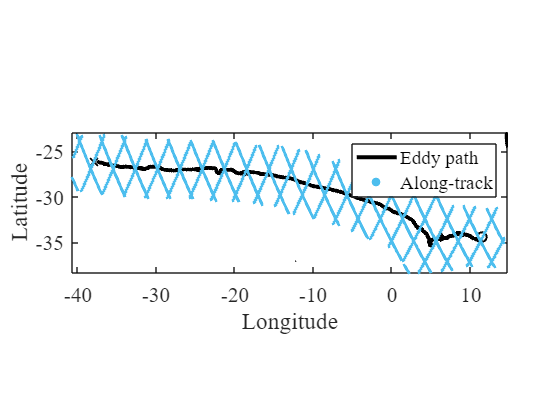

plotAlongtrack(alongtrackLatLon,eddyPath);

clim([-6,25])

%% make video of the propagating eddy
video_name = 'eddy_field_real';
makePropagatingVideo(x,y,eddy_time,eddy_field,video_name)


## 4. Eddy composites

%eddy center from eddyPath_track, which is from ssh max closed contour centroid
%If you want to narrow the time window
time_window=0:length(timeo)-1;
window_idx = find(alongtrackLatLon.t-min(alongtrackLatLon.t) >= time_window(1) & alongtrackLatLon.t-min(alongtrackLatLon.t) <= time_window(end));
alongtrack.t=alongtrackLatLon.t(window_idx);
alongtrack.x=alongtrackXY.x(window_idx);
alongtrack.y=alongtrackXY.y(window_idx);
alongtrack.ssh=alongtrackLatLon.ssh(window_idx);

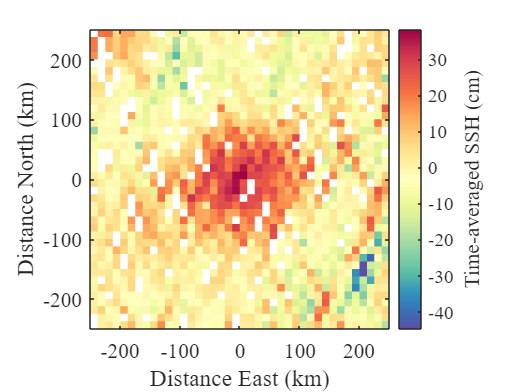

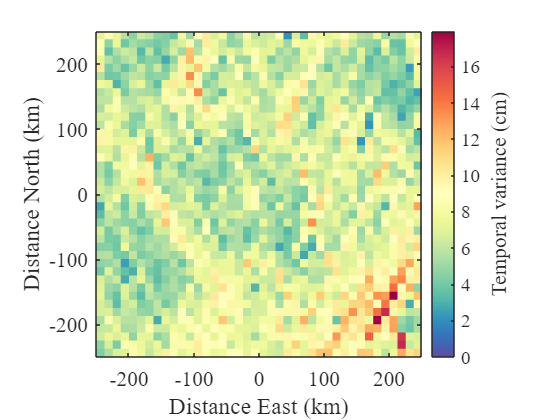

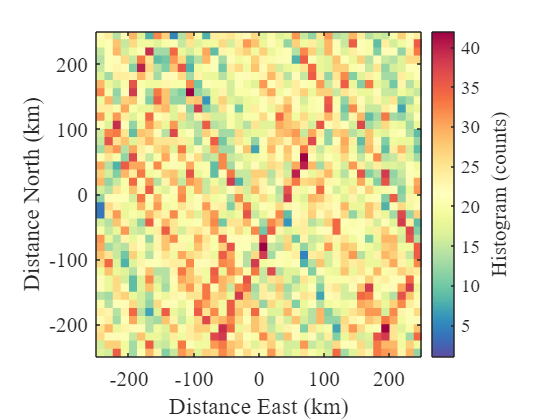

% time-averaged eddy composite
[mz_xy, xmid_xy, ymid_xy, numz_xy, stdz_xy] = composite2D(alongtrack,eddyPath_fun_t);% options: bin_size=12.5*1e3

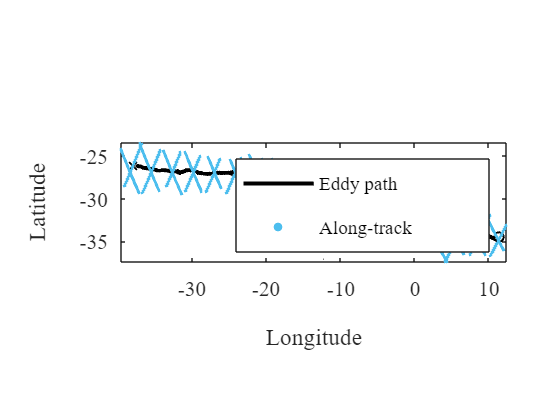

% time-averaged radial profile
[mz_r, rmid_r, numz_r, stdz_r] = radialProfile(alongtrack,eddyPath_fun_t);

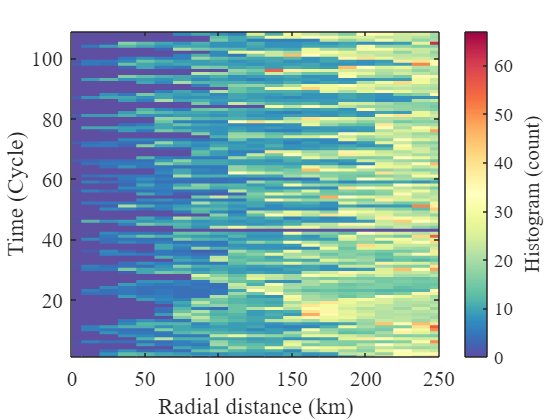

% radialProfile over time
[mz_rt, rmid_rt, tmid_rt, numz_rt, stdz_rt] = radialProfileTime(alongtrack,eddyPath_fun_t);

## 5. Parameter extraction from mapped product

%%
% [center_zeta,amplitude,radius,core_zeta,shield_zeta] = findEddyCentroid(x, y, ssh,'BoundaryType','zero-zeta','lato',24,'GetBoundary', true,'epsilon',0.01);
amplitude = ncread(filename,'eddy/amplitude')*100;
radius = ncread(filename,'eddy/speed_radius')/1e3;

% Calculate grid spacing
dx = x(2) - x(1);
dy = y(2) - y(1);
% calculate zeta in (x,y,t) matrix
[zeta] = zetaField(dx,dy,ssh,lato=lato);

n=260;
zetaContours.core=core_zeta{n};
zetaContours.shield=shield_zeta{n};
plotComposite(x,y,t(n),zeta(:,:,n),eddyPath_fun_t,contour=zetaContours)
hold on
text(-245,270,['Day ',num2str(n)],'FontSize',14,'FontName','times')
[center_xoyo,amplitude,radius,core_xy] = findEddyCentroid(x, y, ssh,'thresholdratio',0.9,'GetBoundary', true);
plotParameters(alongtrack)

## 5. Convergence Rate

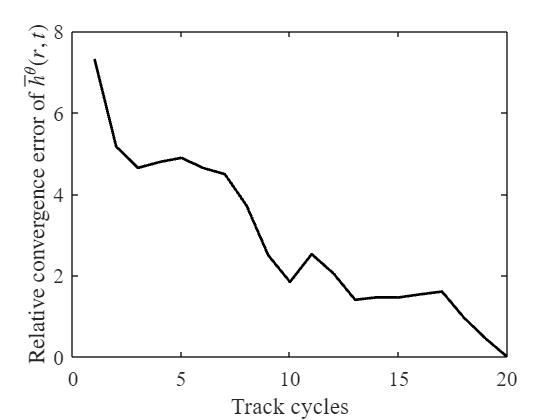

% how many cycles are needed to reach convergence to time-averaged profile
[convergence] = convergenceRate(mz_rt, numz_rt);

## 6. Gaussian fit

eddyFit_fun = @(x,y,t,A,L,x0,y0,cx,cy) A.*exp(-((x-x0-cx*t).^2 + (y-y0-cy*t).^2)/L^2);
x0 = 500e3; y0 = 0e3; vx = -2.0e3; vy = -0.5e3;
true_params.A = 0.15;%max(ssh(:,:,n));
true_params.L = 80e3;
true_params.x0 = x0;
true_params.y0 = y0;
true_params.cx = vx;
true_params.cy = vy;

initParams.A = true_params.A-0.02;
initParams.L = true_params.L+5e3;
initParams.x0 = true_params.x0-50e3;
initParams.y0 = true_params.y0+50e3;
initParams.cx = true_params.cx-0.2e3;
initParams.cy = true_params.cy+0.2e3;

plot_func = @(xtrans, optimValues, state) plotParamsIteration_ref(xtrans, optimValues, state, [], true_params);
it_options = optimset('OutputFcn', plot_func,'TolX',1e-3,'TolFun',1e-3);
paramsFit = FitAlongTrackXYToEddyModel(alongtrack, eddyFit_fun, initParams, it_options);
plotFitPosition(paramsFit,true_params)
xlim([min(x),max(x)]);ylim([min(y),max(y)])

%% time windowed fit
it_options = optimset('TolX',1e-3,'TolFun',1e-3);
[paramsCell, initParamsCell] = FitAlongTrackXYToEddyModelWindowed(alongtrack, eddyFit_fun, initParams, eddyPath_fun_t, it_options);
plotFitPosition(paramsCell,initParamsCell)
xlim([min(x),max(x)]);ylim([min(y),max(y)])
plotFitWindowed(paramsCell,true_params, eddyPath_fun_t)
